## Question 5

rng(0); %setting the seed

Creating an array with all the values of N's

n = zeros(1, 10);
n(1, 1) = 5;
n(1, 2) = 10;
n(1, 3) = 20;
n(1, 4) = 40;
n(1, 5) = 60;
n(1, 6) = 80;
n(1, 7) = 100;
n(1, 8) = 500;
n(1, 9) = 1000;
n(1, 10) = 10000;

Creating a 2D array to store experimental error for all the values of N

Each column contains 100 error values for that respective N

vals = zeros(100, 10);

#### Uniform Distribution

Calculating the average for each experiment and then storing the error in the above declared array

For Uniform Distribution, true average will be 0.5

for i=1:1:10 %iterating through all values of N
    for j=1:1:100 %iterating throug 100 experiments
        random = rand(1, n(1, i)); %using random number gernerator as we have uniform distribution
        mu = 0; %variable to store experimental average
        for k=1:1:n(1, i) %iterating through N number of cases
            mu = mu + random(1, k)/n(1, i); %calculating the average
        end
        vals(j, i) = abs(mu - 0.5); %storing the error using true mean as 0.5
    end
end

Plotting the box-and-whisker plot for normal distribution

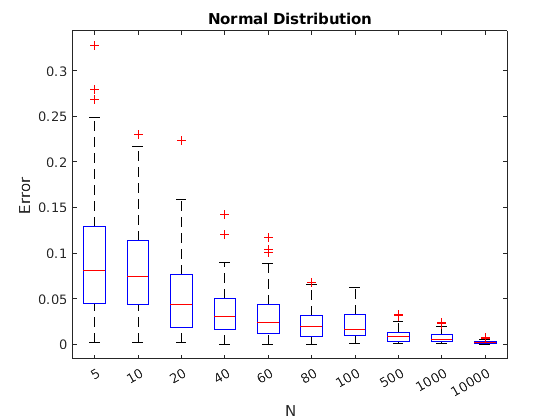

boxplot(vals, 'Labels', {'5', '10', '20', '40', '60', '80', '100', '500', '1000', '10000'});
xlabel("N")
ylabel("Error")
title("Normal Distribution")

#### Gaussian Distribution


$$\mu=0$$



$$\sigma=1$$


so the true average for this gaussian distribution will be 0.

for i=1:1:10
    for j=1:1:100
        random = normrnd(0, 1, 1, n(1, i)); %generating gaussian random numbers
        mu = 0;
        for k=1:1:n(1, i)
            mu = mu + random(1, k)/n(1, i);
        end
        vals(j, i) = abs(mu);
    end
end

Plotting the box-and-whisker plot for gaussian distribution

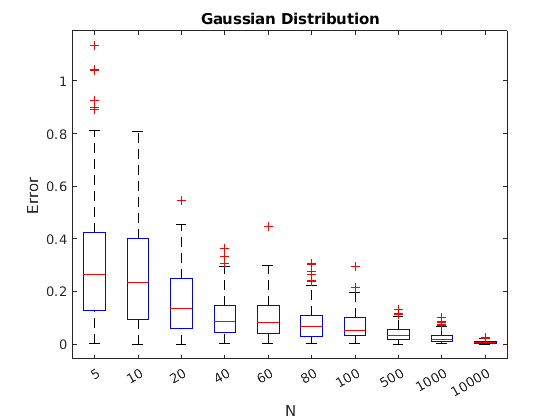

boxplot(vals, 'Labels', {'5', '10', '20', '40', '60', '80', '100', '500', '1000', '10000'});
xlabel("N")
ylabel("Error")
title("Gaussian Distribution")